# Lec 9 Sampling Theorem

## Sampling of Continuous Signals

The issue of sampling continuous signals requires time to develop. There is a difference between ideal theoretical sampling and practical sampling. There is also quantization that occurs when using an A/D converter to quantize a signal amplitude.

Nevertheless, we have to show that it makes sense to convert continuous signals to discrete signals for computers. We have not shown this yet. It is now time to prove this.

We will start by considering ideal theoretical sampling. This is referred to in the text as Ideal Continuous-to-Discrete conversion as shown below.

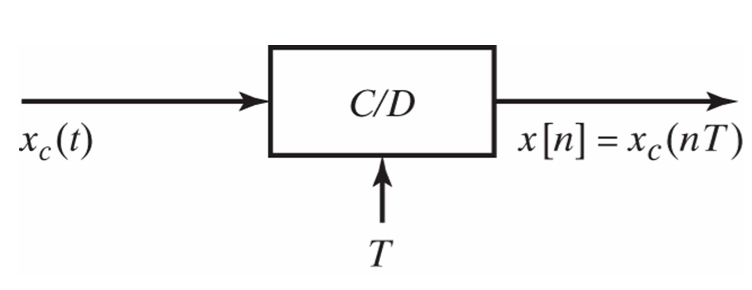

The concept of an ideal C/D converter involves multiplying by an impulse train and changing the impulse train to a discrete-time sequence. This is illustrated in the figure below taken from the textbook.

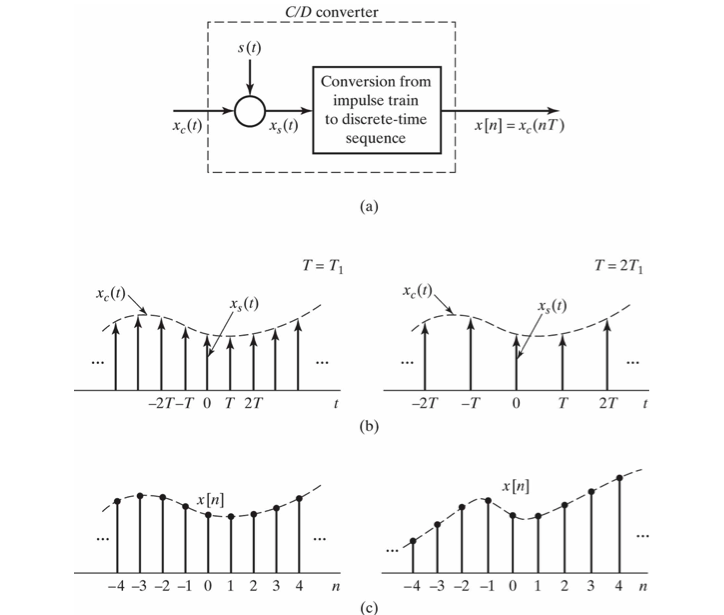

I will now try to develop an intuitive understaning of the **Whittaker-Shannon Sampling Theorem.**

## **Sampling and Aliasing Cartoon**

We will begin with the big picture and later delve into the mathematical details.

# Sampling and Aliasing Cartoons

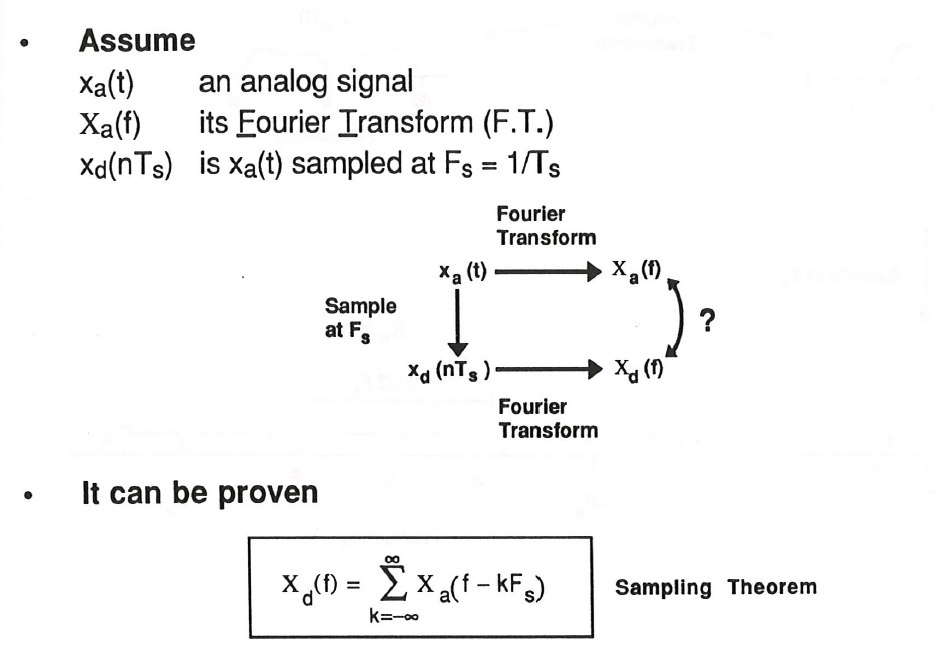

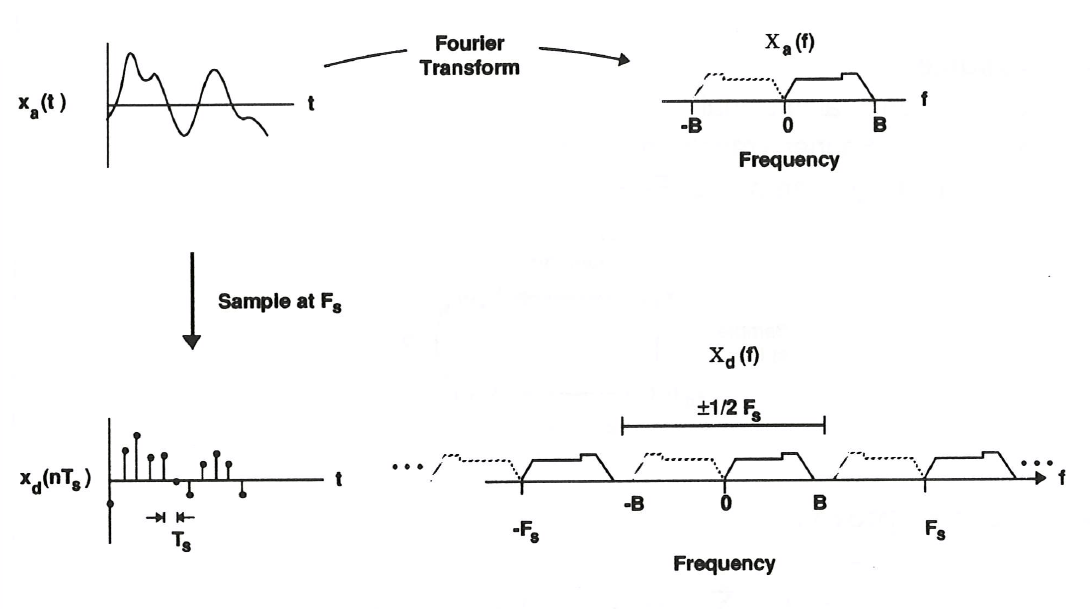

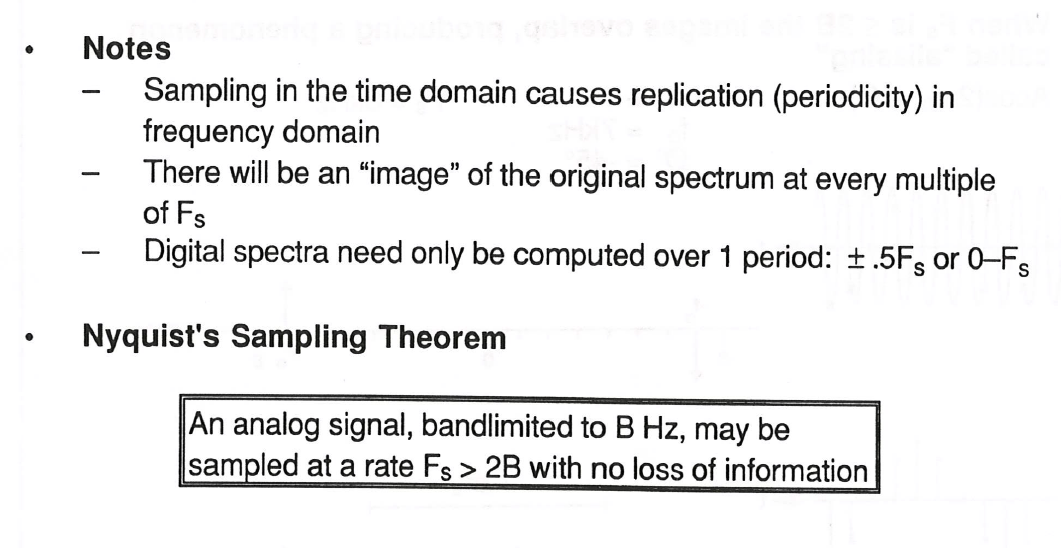

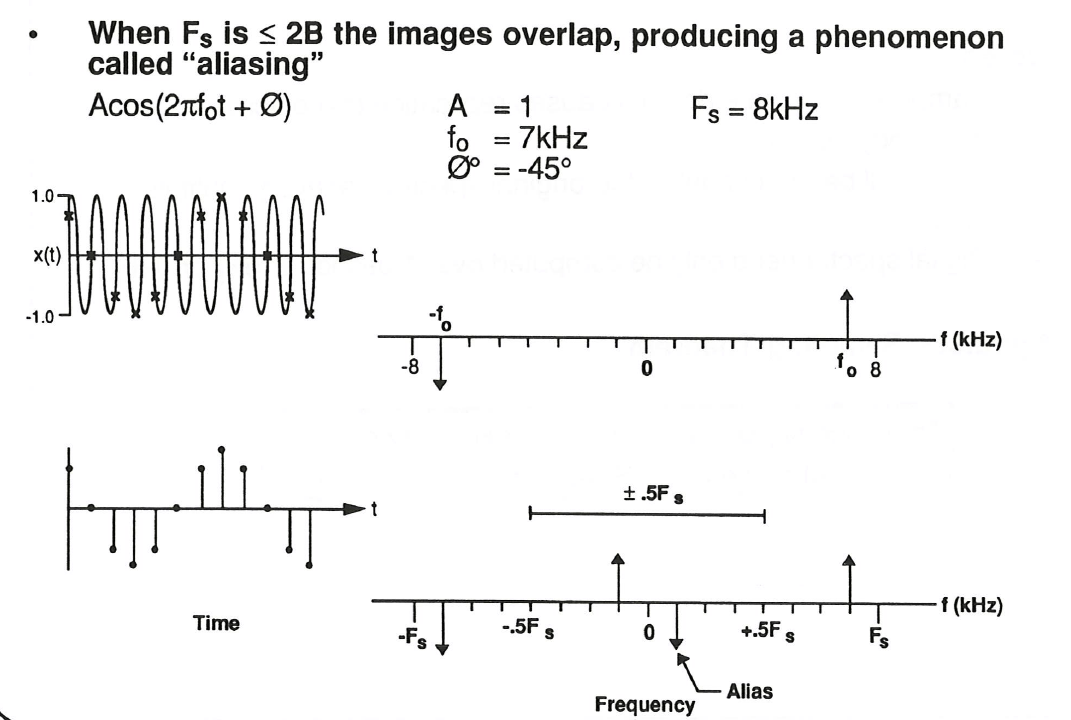

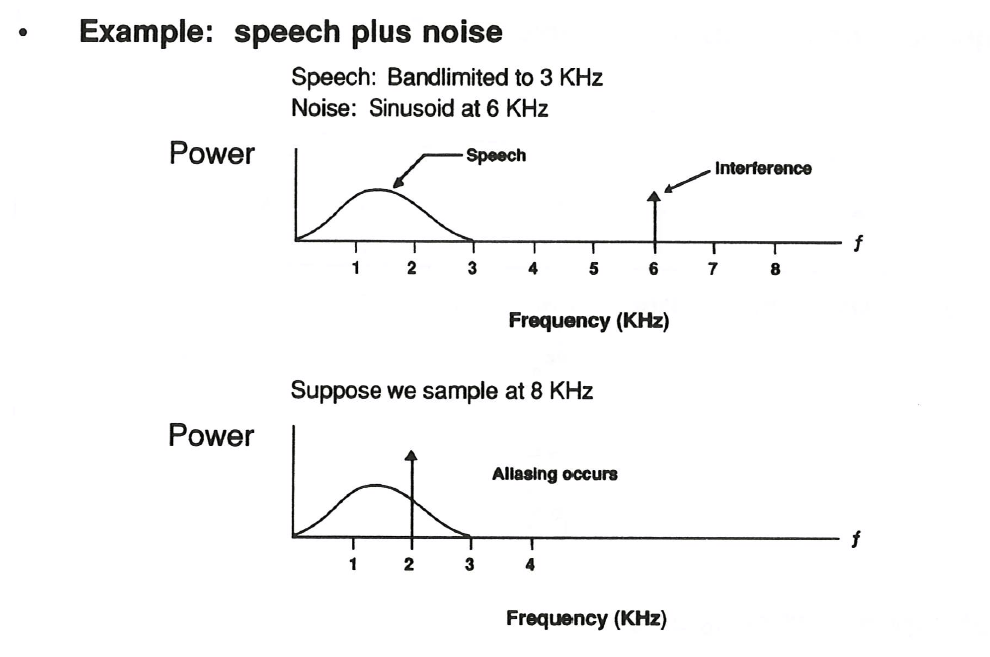

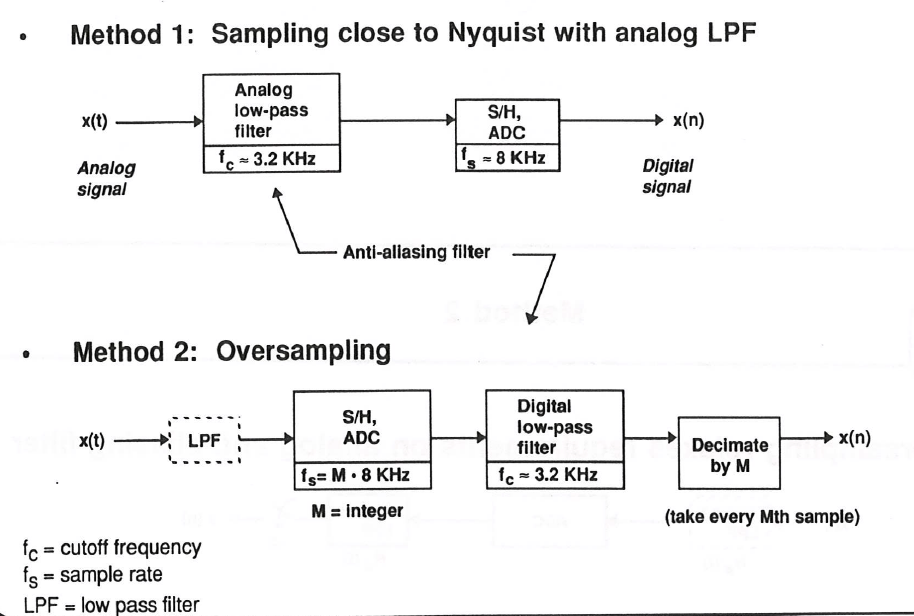

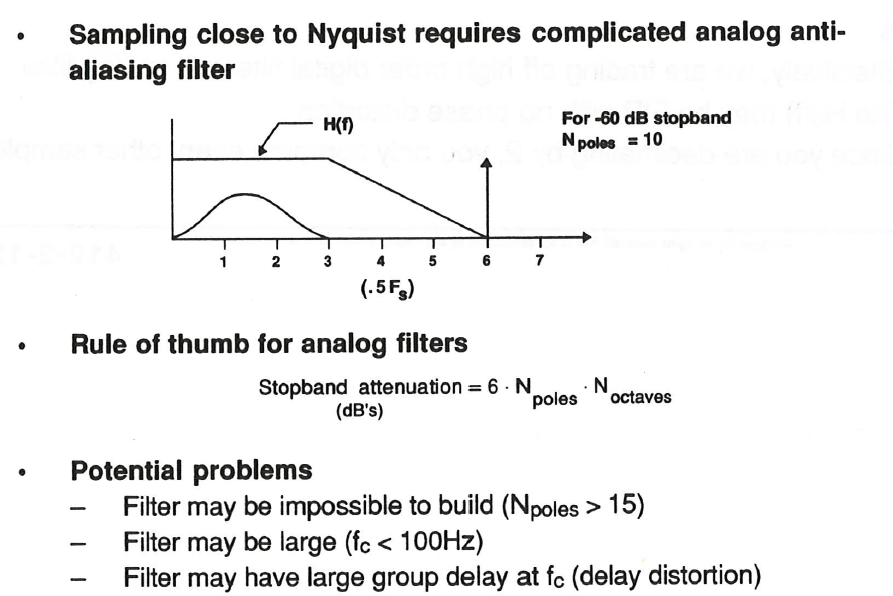

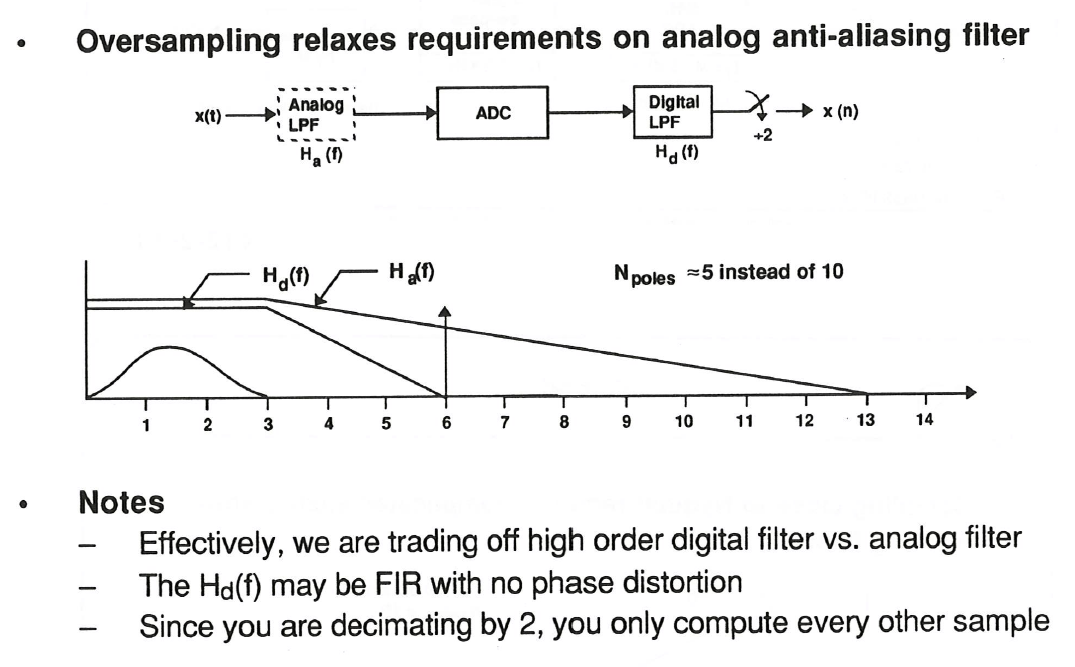

# Mathematical Details of the Sampling Theorem

## **Continuous Time Fourier Transform**

The Sampling Theorem is closely related to what is known as the Poisson Summation formula. Both are proved in a similar manner. 

The crux of the Sampling Theorem is to combine the Complex Fourier Series with the Continuous Time Fourier Transform.

Let's begin with the Continuous Time Fourier Transform.

The Continuous TIme Fourier Transform relates to the fact that:


$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}d\Omega\int_{-\infty}^{\infty}x_{a}(t)\cos\left(j\,\Omega\,(t-s)\right)ds$$



$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}d\Omega\int_{-\infty}^{\infty}x_{a}(t)e^{j\,\Omega\,(t-s)}ds$$


These integral expressions for $x_{a}(t)$suggest there is an even function of t-s that picks out a single value of $x_a(t)$. In truth, the function is a generalized function known as a linear functional and it is referred to as the Dirac delta function:


$$\frac{1}{2\,\pi}\int_{-\infty}^{\infty}e^{j\,\Omega(t-s)}d\Omega = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}\cos\left(\Omega(t-s)\right)d\Omega = \delta(t-s)$$



$$x_{a}(t) = \int_{-\infty}^{\infty}x_{a}(s)\delta(t-s)ds$$


Given this form for the Dirac delta function, we can split out the two integrals shown earlier and obtain the Continuous Time Fourier Transform as shown below:


$$X_{a}(j\,\Omega) = \int_{-\infty}^{\infty}x_{a}(t)e^{-j\,\Omega\,t}dt$$



$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}X_{a}(j\,\Omega)e^{j\,\Omega\,t}d\Omega$$


If we substitute one equation into the other we obtain:


$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}\left(\int_{-\infty}^{\infty}x_{a}(s)e^{-j\,\Omega\,s}ds\right)e^{j\,\Omega\,t}d\Omega$$



$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}d\Omega\int_{-\infty}^{\infty}x_{a}(s)e^{j\,\Omega\,(t-s)}ds$$



$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}d\Omega\int_{-\infty}^{\infty}x_{a}(t)e^{j\,\Omega\,(t-s)}ds$$


## Whittaker-Shannon Sampling Theorem

For the Sampling Theorem, we will use the following symmetric form of the Continuous Fourier transform:


$$X_{a}(j\,2\,\pi\,f) = \int_{-\infty}^{\infty}x_{a}(t)e^{-j\,2\,\pi\,f\,t}dt$$



$$x_{a}(t) = \int_{-\infty}^{\infty}X_{a}(j\,2\,\pi\,f)e^{j\,2\,\pi\,f\,t}df$$


We now consider a band-limited function $x_{a}(t)$ such that its Fourier Transform has the property that it is zero outside a specified frequency band:


$$X_{a}(j\,2\,\pi\,f) = 0 \ \ \text{for} \ \ |f| > F_{B} \ \text{.}$$


Why do we make $X_{a}(j\,2\,\pi\,f)$band-limited ? We do this so we can express it as a continuous Fourier series !!

We have:


$$X_{a}(j\,2\,\pi\,f) = \sum_{n=-\infty}^{\infty}C_{n}e^{j\,n\,\frac{2\,\pi}{2\,F_{b}}\,f}$$



$$C_{n} = \frac{1}{2F_{B}}\int_{-F_{B}}^{F_{B}}X_{a}(j\,2\,\pi\,f)e^{-j\,n\,\frac{2\,\pi}{2F_{B}}\,f}df$$


Thus, we have two expressions for $X_{a}(j\,2\,\pi\,f)$ - the Fourier transform expression and the Fourier series expression:


$$X_{a}(j\,2\,\pi\,f) = \int_{-\infty}^{\infty}x_{a}(t)e^{-j\,2\,\pi\,f\,t}dt$$



$$X_{a}(j\,2\,\pi\,f) = \sum_{n=-\infty}^{\infty}C_{n}e^{j\,n\,\frac{2\,\pi}{2\,F_{b}}\,f}$$


Note that the Fourier series expression involves discrete coefficients which relates to discrete sampling. Let's see how.

We have:


$$C_{n} = \frac{1}{2F_{B}}\int_{-F_{B}}^{F_{B}}X_{a}(j\,2\,\pi\,f)e^{-j\,n\,\frac{2\,\pi}{2F_{B}}\,f}df$$



$$C_{n} = \frac{1}{2F_{B}}\int_{-\infty}^{\infty}X_{a}(j\,2\,\pi\,f)e^{-j\,n\,\frac{2\,\pi}{2F_{B}}\,f}df \ \ \text{because it's band-limited}$$



$$C_{n} = \frac{1}{2\,F_{B}}x_{a}\left(\frac{-n}{2\,F_{B}}\right) \ \text{.}$$


**Question: What just happened above - provide the explanations for each step ?**

We see that the Fourier coefficients are simply related to discrete samples of $x_{a}(t)$.

Ok, let's continue.

This means we have:


$$X_{a}(j\,2\,\pi\,f) = \sum_{n=-\infty}^{\infty}\frac{1}{2\,F_{B}}x_{a}\left(\frac{-n}{2\,F_{B}}\right)e^{j\,n\,\frac{2\,\pi}{2\,F_{b}}\,f}$$



$$X_{a}(j\,2\,\pi\,f) = \sum_{n=-\infty}^{\infty}\frac{1}{2\,F_{B}}x_{a}\left(\frac{n}{2\,F_{B}}\right)e^{-j\,n\,\frac{2\,\pi}{2\,F_{b}}\,f}$$


Let's now substitute the Fourier series expansion for $X_{a}(j\,2\,\pi\,f)$into the Fourier transform:


$$x_{a}(t) = \int_{-\infty}^{\infty}X_{a}(j\,2\,\pi\,f)e^{j\,2\,\pi\,f\,t}df$$



$$x_{a}(t) = \int_{-F_{B}}^{F_{B}}X_{a}(j\,2\,\pi\,f)e^{j\,2\,\pi\,f\,t}df$$



$$x_{a}(t) = \int_{-F_{B}}^{F_{B}} \left[\sum_{n=-\infty}^{\infty}\frac{1}{2\,F_{B}}x_{a}\left(\frac{n}{2\,F_{B}}\right)e^{-j\,n\,\frac{2\,\pi}{2\,F_{b}}\,f}\right]e^{j\,2\,\pi\,f\,t}df$$



$$x_{a}(t) = \frac{1}{2\,F_{B}}\sum_{n=-\infty}^{\infty}x_{a}\left(\frac{n}{2\,F_{B}}\right)\int_{-F_{B}}^{F_{B}} e^{-j\,n\,\frac{2\,\pi}{2\,F_{b}}\,f}e^{j\,2\,\pi\,f\,t}df$$



$$x_{a}(t) = \frac{1}{2\,F_{B}}\sum_{n=-\infty}^{\infty}x_{a}\left(\frac{n}{2\,F_{B}}\right)\int_{-F_{B}}^{F_{B}} e^{j\,2\,\pi\,f\left[t - n/(2F_{B})\right]}df$$



$$x_{a}(t) = \frac{1}{2\,F_{B}}\sum_{n=-\infty}^{\infty}x_{a}\left(\frac{n}{2\,F_{B}}\right)\left[\frac{e^{j\,2\,\pi\,f\left[t - n/(2F_{B})\right]}}{j\,2\,\pi\,f\left[t - n/(2F_{B})\right]}\right]_{-F_{B}}^{F_{B}}$$



$$x_{a}(t) = \frac{1}{2\,F_{B}}\sum_{n=-\infty}^{\infty}x_{a}\left(\frac{n}{2\,F_{B}}\right)\frac{\sin\left[2\,\pi\,F_{B}\left(t - n/(2F_{B})\right)\right]}{\pi\left[t - n/(2F_{B})\right]}$$



$$x_{a}(t) =\sum_{n=-\infty}^{\infty}x_{a}\left(\frac{n}{2\,F_{B}}\right)\frac{\sin\left[2\,\pi\,F_{B}\left(t - n/(2F_{B})\right)\right]}{2\,\pi\,F_{B}\left[t - n/(2F_{B})\right]}$$


**Question: Provide explanations for each step above ?**

The last expression is the famous reconstruction formula associated with the Sampling Theorem:

When $X_{a}(j\,2\,\pi\,f) = 0 \ \ \text{for} \ \ |f| > F_{B} $, we have:


$$x_{a}(t) =\sum_{n=-\infty}^{\infty}x_{a}\left(\frac{n}{2\,F_{B}}\right)\frac{\sin\left[2\,\pi\,F_{B}\left(t - n/(2F_{B})\right)\right]}{2\,\pi\,F_{B}\left[t - n/(2F_{B})\right]} \ \text{.}$$


Let's now summarize the Sampling Theorem by saying what we did, but not going through all the maths. We did the following:

We started with the continuous Fourier transform for a time signal. We assumed the Fourier transform was band-limited in the frequency domain. This allowed us to express the Fourier transform as a continuous Fourier series. The coefficients of the Fourier series were simply samples of the time signal. We substituted the Fourier series representation back into the inverse Fourier transform and obtained the Sampling Theorem.

## Aliasing

Think very, very carefully now. When we represented the continuous Fourier transform as a Fourier series - we made it **periodic !!!**

**Question: Why ?**

Answer: The Fourier series is always used to represent a periodic function. It is made of sinusoidal signals or complex sinusoidal signals. Sinusoidal signals are periodic and every Fourier series represents a periodic function.

Therefore, when we sample a continuous signal, we are making its Fourier transform periodic because the time samples are implicitly the coefficients of a Fourier series. This is the best and most intuitive way to understand aliasing.

We can explicitly show aliasing with the following maths.

Let 


$$x_{a}(t) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}X_{a}(j\,\Omega)e^{j\,\Omega\,t}d\Omega$$


This means:


$$x[n] = x_{a}(nT) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}X_{a}(j\,\Omega)e^{j\,\Omega\,nT}d\Omega \ \text{,}$$


where T is some sampling period.

For the DTFT, we want to express x[n] as:


$$x[n] = \frac{1}{2\,\pi}\int_{-\pi}^{\pi}X(e^{j\,\omega})e^{j\,\omega\,n}d\omega$$


Consider the following maths:


$$x[n] = x_{a}(nT) = \frac{1}{2\,\pi}\int_{-\infty}^{\infty}X_{a}(j\,\Omega)e^{j\,\Omega\,nT}d\Omega$$



$$x[n] = \frac{1}{2\,\pi}\sum_{r=-\infty}^{\infty}\int_{(2r-1)\pi/T}^{(r2+1)\pi/T}X_{a}(j\,\Omega)e^{j\,\Omega\,nT}d\Omega$$



$$x[n] = \frac{1}{2\,\pi}\sum_{r=-\infty}^{\infty}\int_{-\pi/T}^{\pi/T}X_{a}(j\,[\Omega + 2\pi\,r/T])e^{j\,\Omega\,nT}e^{j\,2\,\pi\,r\,n}d\Omega$$


Let $\Omega \cdot T = \omega$, we then have:


$$x[n] = \frac{1}{2\,\pi}\int_{-\pi/T}^{\pi/T}\sum_{r=-\infty}^{\infty}X_{a}(j\,[\Omega + 2\pi\,r/T])e^{j\,\Omega\,nT}d\Omega \ \text{because} \ e^{j\,2\,\pi\,r\,n} = 1$$



$$x[n] = \frac{1}{2\,\pi}\int_{-\pi}^{\pi}\frac{1}{T}\sum_{r=-\infty}^{\infty}X_{a}(j\,[\omega/T + 2\pi\,r/T])e^{j\,\omega\,n}d\omega$$


Comparison of the above experession with


$$x[n] = \frac{1}{2\,\pi}\int_{-\pi}^{\pi}X(e^{j\,\omega})e^{j\,\omega\,n}d\omega$$


shows that 


$$X(e^{j\,\omega}) = \frac{1}{T}\sum_{r=-\infty}^{\infty}X_{a}(j\,[\omega/T + 2\pi\,r/T])$$


**Question: Provide explanations for every step above.**

## **Poisson Summation Formula**

One can basically repeat the steps above to show that if we have a periodic function $x_a(t)$with period $T$which we can represent using a Fourier series and we consider the Fourier transform pair:


$$X_{a}(f) = \int_{-\infty}^{\infty}x_{a}(t)e^{-j\,2\,\pi\,f\,t}dt$$



$$x_{a}(t) = \int_{-\infty}^{\infty}X_{a}(f)e^{j\,2\,\pi\,f\,t}df$$


then


$$\sum_{n=-\infty}^{\infty}x_{a}(nT) = \frac{1}{T}\sum_{m=-\infty}^{\infty}X_{a}(m/T)$$


The formula above is referred to as the Poisson Summation Formula and provides a relationship between a summation of sampled values of a periodic signal and sampled values of its Fourier transform. However, there is more magic to the Poisson Summation Formula. It turns out that the periodic summation of an aperiodic function is periodic - think about it. Both sides of the Poisson Summation Formula are periodic summations. Therefore, the Poisson Summation Formula holds even when $x_a(t)$ is not periodic !!

So how does this help with understanding sampling and aliasing?

Well, we can simply start with the DTFT formula:


$$X(e^{j\,\omega}) = \sum_{k=-\infty}^{\infty}x(kT)e^{-j\,k\,\omega} =  \sum_{k=-\infty}^{\infty}x(kT)e^{-j\,kT\,\omega/T}\ \text{.}$$


We can then directly use the Poisson Summation Formula to conclude that:


$$X(e^{j\,\omega}) = \sum_{k=-\infty}^{\infty}x(kT)e^{-j\,kT\,\omega/T} = \frac{1}{T}\sum_{k=-\infty}^{\infty}\mathcal{F}\left(x_a(t)e^{-j\,t\,\omega/T}\right)|_{k/T}$$



$$X(e^{j\,\omega}) = \frac{1}{T}\sum_{k=-\infty}^{\infty}X_{a}(f+\omega/T)|_{k/T} = \frac{1}{T}\sum_{k=-\infty}^{\infty}X_a(k/T + \omega/T) \ \text{.}$$


This is similar to the aliasing formula above. It is different because we have actually defined the function $X_a(\cdot)$ differently - one in terms of $f $and the other in terms of $j\,\omega$. To obtain the same form as above, we have to let $f \rightarrow2\,\pi\,\omega \Rightarrow k/T \rightarrow 2\,\pi\,k/T$ and put in multiplication by $j$.

## Poisson Summation Formula and Dirac Combs

Many textbooks and authors like to speak about Sampling from the point of view of Dirac Combs. Let's see how this perspective works. We start with the Poisson Summation Formula:


$$\sum_{n=-\infty}^{\infty}x_{a}(nT) = \frac{1}{T}\sum_{m=-\infty}^{\infty}X_{a}(m/T)$$


We can then re-write this as:


$$\sum_{n=-\infty}^{\infty}\int_{-\infty}^{\infty}\delta(t-nT)x_a(t)dt = \frac{1}{T}\sum_{m=-\infty}^{\infty}\int_{-\infty}^{\infty}x_a(t)e^{-j\,m\left(\frac{2\,\pi}{T}\right)\,t}dt$$


Switch the order of summation and integration:


$$\int_{-\infty}^{\infty}\sum_{n=-\infty}^{\infty}\delta(t-nT)x_a(t)dt = \frac{1}{T}\int_{-\infty}^{\infty}\sum_{m=-\infty}^{\infty}x_a(t)e^{-j\,m\left(\frac{2\,\pi}{T}\right)\,t}dt$$


Stare real hard at this equation and realise that this means:


$$T\sum_{n=-\infty}^{\infty}\delta(t-nT) = \sum_{m=-\infty}^{\infty}e^{-j\,m\left(\frac{2\,\pi}{T}\right)t} \ \text{.}$$


Of course, generalised functions like the Dirac delta function only take their meaning from integration. Nonetheless, it is interesting to see that the periodic summation of the exponential function is a Dirac comb (this is how we refer to the left-hand side). Please note that the delta functions are not unit-sample functions, but real Dirac deltra functions!

Now, here is a weird queston - how do we take the Fourier Transform of a Dirac Comb? Remember, the Dirac Comb is a generalised function. So what does it even mean to take the Fourier Transform of a Dirac Comb? Well, what you do is utilise the fact that the Fourier Transform is an isometry - it preserves lengths and inner products. In other words: $<x(t),y(t)> \ = \ <X(f),Y(f)>$.  So, we define the Fourier Transform of a Dirac Comb and other generalised functions via inner products.

So watch and consider:


$$\int_{-\infty}^{\infty}\overline{g(t)}\sum_{n=-\infty}^{\infty}\delta(x-nT)dt = \sum_{n=-\infty}^{\infty}\,\overline{g(nT)}$$


Assert (insist by definition) that:


$$\int_{-\infty}^{\infty}\overline{G(f)}\,H(f)df = \sum_{n=-\infty}^{\infty}\,\overline{g(nT)}$$


where $H(f)$is the Fourier Transform of the Dirac Comb.

Use our Poisson Summation Formula:


$$\int_{-\infty}^{\infty}\overline{G(f)}\,H(f)df = \frac{1}{T}\sum_{n=-\infty}^{\infty}\,\,\overline{G(n/T)}$$


Realise that:


$$\int_{-\infty}^{\infty}\overline{G(f)}\,H(f)\,df = \int_{-\infty}^{\infty}\overline{G(f)}\,\sum_{n=-\infty}^{\infty}\frac{1}{T}\delta(f - n/T)\,df$$


Thus, we learn that:


$$\mathcal{F}\left\{\sum_{n=-\infty}^{\infty}\delta(x - nT)\right\} = \frac{1}{T}\sum_{n=-\infty}^{\infty}\delta(f - n/T)$$


In engineering, we write Dirac Combs using the following short-hand:


$$III_T = \sum_{n=-\infty}^{\infty}\delta(x-nT)$$


Thus, we have:


$$\mathcal{F}\left\{III_T\right\} = \frac{1}{T}\,III_{1/T}$$


## Sampling Using Dirac Combs

Sampling a continuous function simply means to multiply it by a Dirac comb:


$$x(nT) = x_a(t)*\,III_T$$


We can now take the Fourier Transform of the equation to get:


$$\mathcal{F}\left\{x(nT)\right\} = X(f)\,\ast\,\frac{1}{T}\,III_{1/T}$$


## Sampling Simulations

We create a sinusoidal reference signal at a very high sample rate. We plot both the signal and its spectrum.

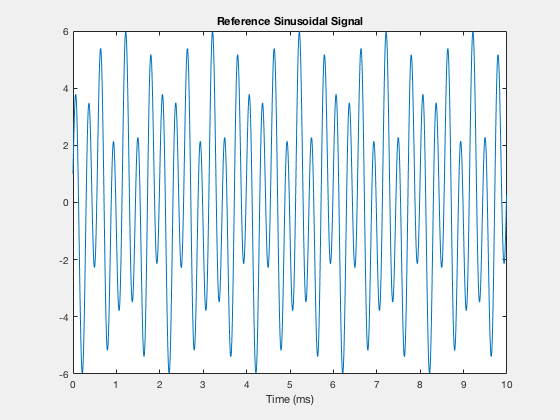

clear all
close all

% Create reference signal and plot
fsRef = 100000 ;
tRef = (0:1/fsRef:2) ;
f1 = 1500 ;
theta1 = pi/3 ;
f2 = 3500 ;
sigRef = 2*cos(2*pi*f1*tRef + theta1) + 4*sin(2*pi*f2*tRef) ;
figure
set(gcf,'Visible','On')
plot(tRef(1:fsRef/100)*1000,sigRef(1:fsRef/100))
title('Reference Sinusoidal Signal')
xlabel('Time (ms)')

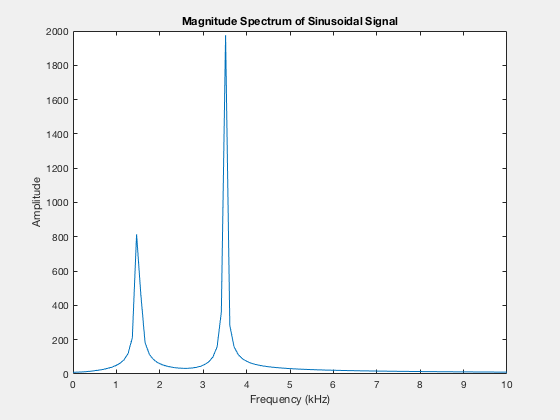


% Perform FFT and plot magnitude spectrum
Nfft = 1024 ;
sigfft = fft(sigRef,Nfft) ;
freq = (0:1023)*fsRef/Nfft ;
figure
set(gcf,'Visible','On')
plot(freq(1:513)/1000,abs(sigfft(1:513)))
xlim([0 10])
title('Magnitude Spectrum of Sinusoidal Signal')
xlabel('Frequency (kHz)')
ylabel('Amplitude')

We sample the reference signal at a lower sample rate.

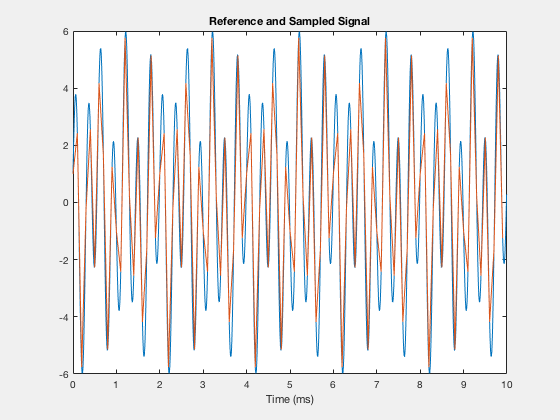

% Sample Reference signal at 10 kHz
close all

% Set sample rate
fs = 10000 ;
t = (0:1/fs:2) ;
% sample signal, plot and compare with reference
sig = 2*cos(2*pi*f1*t + theta1) + 4*sin(2*pi*f2*t) ;
figure
set(gcf,'Visible','On')
plot(tRef(1:fsRef/100)*1000,sigRef(1:fsRef/100))
hold on
plot(t(1:round(fs/100))*1000,sig(1:round(fs/100)))
title('Reference and Sampled Signal')
xlabel('Time (ms)')

# Sampling Reconstruction

We now use the sampling theorem to reconstruct the signal.

The Sampling Theorem states that we can reconstruct the original signal using the sinc function as follows:


$$x_a(t) = \sum_{n=-\infty}^{\infty}x[n]sinc\left[f_s(t-nT_s)\right]$$


Note that Matlab's sinc function is defined: $\text{sinc}(x) = \frac{\sin(\pi\,x)}{\pi\,x}$

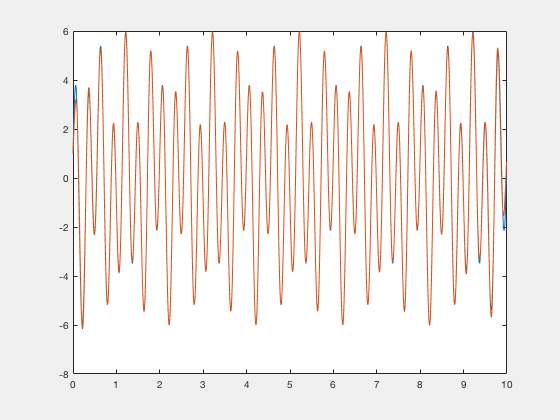

% Perform the sinc reconstruction and compare with reference signal
close all
% Use 100 samples for 10 ms
n = (0:100) ;
% create the sinc argument - use broadcasting to get an array
sinc_arg = fs*(tRef(1:fsRef/100).' - n*(1/fs)) ;
% implement the sinc reconstruction formula
sig_recon = sum( bsxfun(@times,sinc(sinc_arg),sig(1:101)) ,2 ) ;
% plot and compare with the referenc signal
figure
set(gcf,'Visible','On')
plot(tRef(1:fsRef/100)*1000,sigRef(1:fsRef/100))
hold on
plot(tRef(1:fsRef/100)*1000,sig_recon)

**Question: The signal does not match up at the ends - why?**

Answer:

**Question: How do we get an anolog signal from the digital signal ?**

Lab4 % Have to be in correct directory    